clear all, close all, clc;

# Solving Heat Equation using FFT


$$\underline{\text {Heat equation:}} \\
u_t = \alpha ^2 u_{xx} \\
\Downarrow \mathcal{F} \\
\hat{u}_t = -\alpha^2 \kappa ^2 \hat{u} $$



$$\kappa - \text{spatial frequency} \\$$


a = 1;
L = 100;
N = 1000;
dx = L/N;
x = -L/2:dx:L/2-dx;

**Spatial wave numbers**

kappa = (2*pi/L)*[-N/2:N/2-1];
kappa = fftshift(kappa);

**initial conditions**

u0 = 0*x;
u0( (L/2-L/10)/dx:(L/2+L/10)/dx) = 1;

**Solve for **$\hat{u} = f(t)$

t = 0:0.1:20;
rhsHeat = @(t, uhat, kappa, a) -a^2*(kappa.^2)'.*uhat; %differential equation
[t,uhat] = ode45(@(t, uhat) rhsHeat(t, uhat, kappa, a), t, fft(u0));

**iFFT**

for z = 1:length(t)
    u(z, :) = ifft(uhat(z, :));
end

**Plotting**

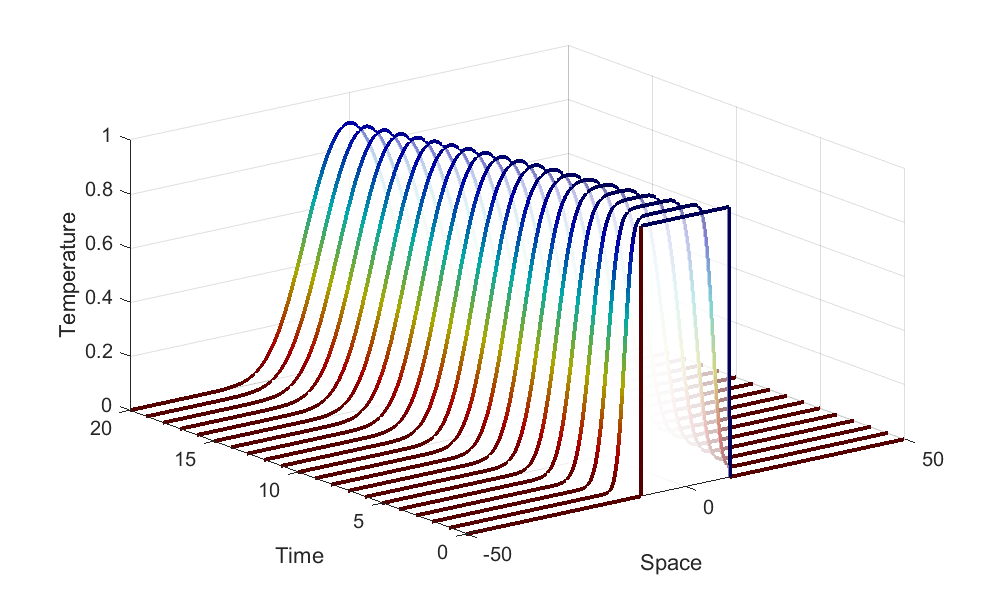

figure('Position',[0 0 1000 600])
h = waterfall(x, t(1:10:end), (u(1:10:end, :)));
set(h, "LineWidth", 3, "FaceAlpha",0.5);
colormap(flipud(jet)/1.5);
set(gca, 'Fontsize', 15);
xlabel('Space'), ylabel('Time'), zlabel('Temperature')